**Dear Students, **

**Welcome to Lab 1 - Part 1 of your EE315 Course!**

**In this lab, we will explore and familiarise ourselves with the differences between continuous-time and discrete-time signals. **

#### **Note: **

- **In this notebook, you are expected to (i) write or/and complete code snippets (ii) write your observations and inferences based on the results of the code. You can write your answers inferences just after the question where ANSWER is mentioned. **

- **If you feel that some information is missing for carrying out your exercises, you can assume them appropriately. Please remember to state your assumptions.  If you find typos in the notebook, please let us know.  **

**You are expected to submit the solved notebook by 24th October 2020, 11.59pm. **

### **References: **

- **https://classroom.google.com/u/0/w/MTUyODczMTg4NDQ2/tc/MTM5MzAwNjc0NjY5**

# **Continuous-Time & Discrete-Time Sinusoids (60 Points)**

**Learning Outcome**: At the end of this exercise, you will be able to find out the differences between the continuous-time and discrete-time sinusoids. 

## Continuous-Time Sinusoids

Recall that the real continuous-time sinusoid is given by

                                                                           
$$x(t) = \cos(\Omega t+\phi), \;\; t\in \mathbb{R}$$
 

In the above equation, $t$ is the independent variable and $\Omega$ (radians/second) and $\phi$(radians) are the parameters, respectively, referred to as the frequency and phase of the continuous-time sinusoid. Note that $\Omega =2\pi \;F$, where $F$ is the frequency in $\textrm{Hz}\ldotp \;$

Now, you will construct and plot a continuous-time sinusoid. Remember that we are working on a digital computer. Hence, you need to devise a way to emulate the continuous-time in a digital computer. 

### **Coding (10 Points):                                                                   **

Question 1: Construct and plot a continuous-time sinusoid when $\Omega =\;\Omega_0 =\frac{\pi }{3}$ radians/second and ${\phi =\phi }_0 =0$ radians (plot $4$ cycles). 

#### **Initialization:                                                                                                                                  **

% Choose appropriate numerical values for the below variable to emulate continuous-time in the digital computer
step = [0.01]    % EXERCISE - Resolution of time variable

step = 0.0100

nCycles = [4] % EXERCISE - Number of cycles required

nCycles = 4

Omega = [(pi/3)];  % EXERCISE - Radian frequency
phi = [0];    % EXERCISE - Phase

period = [2*pi/Omega]  % EXERCISE - Compute the period of the sinusoid

period = 6

t = 0: step: [period*nCycles] % EXERCISE - Fill in the blank to plot 4 cycles of the sinusoid.

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


sinusoidCT =  zeros(1,length(t)); % EXERCISE - this is x(t). Initialize it to zero, for each value of "t"

#### **Construction: **

sinusoidCT =  sinusoidCT+ cos(Omega*t+phi); % EXERCISE - construct continuous-time sinusoid. 

#### **Plotting:**

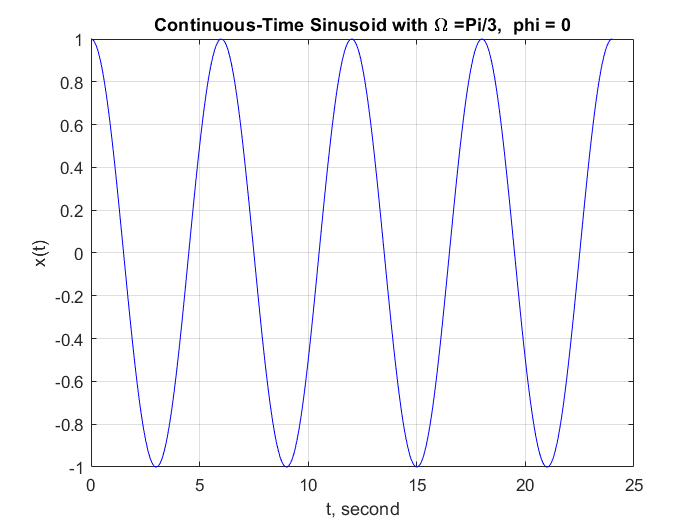

plot(t, sinusoidCT, 'b') 
title('Continuous-Time Sinusoid with \Omega =Pi/3,  phi = 0')
xlabel('t, second')
ylabel('x(t)')
grid

### **Inferences (10 Points):   **

Now, play with the above constructed continuous-time sinusoid, make observations and write down your inference. 

- For any $\Omega$, the  continuous-time sinusoid is (SAY PERIODIC/APERIODIC)

             ANSWER:   Periodic (Sinusoid will appear only when sampling time is comparable or much smaller than period.)

- If you increase $\Omega$, the period  (*COMPLETE THE SENTENCE HERE*).

              ANSWER:  Decreases  (for $\Omega \;=$30$\pi$ the period is 0.02 sec)

- If you increase $\Omega$,  the rate of oscillations  (*COMPLETE THE SENTENCE HERE*).

              ANSWER:  Increases (its inverse of period )

- Can any two continuous sinusoids with two different frequencies be same? *(WRITE YOUR ANSWER HERE)*

              ANSWER:  No they can't be same as will have different periods(unless they get distorted badly)

- What does the variable "step" represent in the above code?

              ANSWER:  Sampling period/ rate . (time interval between two samples)

## **Practical Experiment  (10 Points)**

Now, construct and plot a continuous-time sinusoid when $\Omega =\;\Omega_0 =\frac{\pi }{3}$ radians/second and ${\phi =\phi }_0 =0$ radians. 

omega=2000/pi

omega = 636.6198

period=2*pi/omega

period = 0.0099

step=0.001  %we sample at 1KHz to ensure we get proper values.

step = 1.0000e-03

n=10  % we see for 10 cycles

n = 10

t = 0: step: [period*n]

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


y=cos(omega*t+0)    

y =     1.0000    0.8041    0.2932   -0.3326   -0.8281   -0.9991   -0.7787   -0.2533    0.3714    0.8506    0.9966    0.7520    0.2129   -0.4097   -0.8717   -0.9923   -0.7241   -0.1722    0.4472    0.8913    0.9862    0.6948    0.1312   -0.4839   -0.9093   -0.9785   -0.6644   -0.0899    0.5198    0.9258    0.9692    0.6328    0.0485   -0.5548   -0.9407   -0.9581   -0.6001   -0.0070    0.5888    0.9540    0.9454    0.5664   -0.0345   -0.6219   -0.9656   -0.9310   -0.5317    0.0759    0.6538    0.9756


plot(t, y,'g')
title('Continuous-Time Sinusoid (10 cycles)')
xlabel('t, second')
ylabel('y (value')
grid
t1=0: step/10: [period*n] %we sample at higher frequency(10 KHz) 10 times higher.

t1 =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


y1=cos(omega*t1+0)

y1 =     1.0000    0.9980    0.9919    0.9818    0.9678    0.9498    0.9279    0.9023    0.8731    0.8403    0.8041    0.7647    0.7221    0.6766    0.6284    0.5777    0.5246    0.4693    0.4122    0.3534    0.2932    0.2318    0.1694    0.1064    0.0429   -0.0208   -0.0843   -0.1475   -0.2102   -0.2719   -0.3326   -0.3919   -0.4497   -0.5056   -0.5594   -0.6110   -0.6602   -0.7066   -0.7502   -0.7907   -0.8281   -0.8621   -0.8926   -0.9194   -0.9426   -0.9619   -0.9774   -0.9888   -0.9963   -0.9998


% Enter your code heres

Write code to listen to the above generated signal. Note that you will need to associate your variable "t" with the physical time to listen the true signal of frequency $\Omega$. (see [sound](https://in.mathworks.com/help/matlab/ref/sound.html)) 

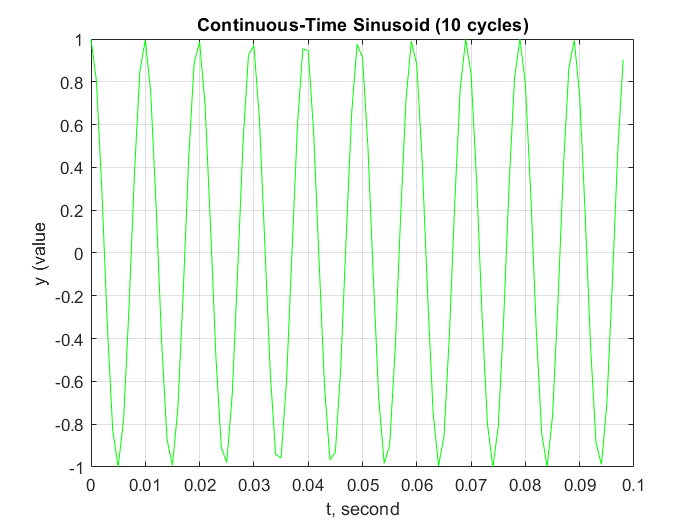

sound(y)      %y is generated by sampling at 1KHz
pause(2)      %Pausing 2 seconds in between to get difference

sound(y1)       %we have sampled y1 at higher frequency (10 KHz). 

- What sampling frequency did you use in the above code? Why? 

              ANSWER:  The  sampling frequency of  1000 HZ and 10000 Hz 

                                 (10 times that) We had to take sampling frequency greater         

                                  than frequency of singal to get it right and as we can hear 

                                  sounds from 20 Hz to 20KHz normally so any lower or 

                                  higher sampling frequency will not be audible.

- Change the sampling frequency while playing the sound and listen to the sound. What happens when you increases and decrease the sampling frequency? 

              ANSWER: The sound plays with higher loudness and sharpness as 

                                sampling frequency is reduced for same signal. 

## Discrete-Time Sinusoids

Now, let us sample the continuous-time sinusoid with the sampling frequency, $F_s \ge 2F$. Let us select, $F_s =\;\;2$ Hz implying that $T_s =0\ldotp 5$second. 

In this case, we are going to take samples of $x\left(t\right)$ at  $t=0T_{s\;} ,1T_s ,2T_s$and so on and we will get the following sequence: $\left\lbrace x\left\lbrack 0\right\rbrack \;=\;x\left(0T_s \right),\;x\left\lbrack 1\right\rbrack \;=\;x\left(1T_s \right),\;x\left\lbrack 2\right\rbrack \;=\;x\left(2T_s \right),\dots \right\rbrace \ldotp \;$

Compactly, this can be denoted as 

                                                                $x\left\lbrack n\right\rbrack =\;\cos \left(\Omega \;T_{s\;} n+\phi \right)\;=\;\cos \left(\omega \;n+\phi \right),\;\;\;\;n\in Z$, 

where  $\omega =\Omega \;T_s$ with radians/sample as the unit. We refer to $\omega$ as the discrete-time frequency, due to its similarity to the continuous-time frequency (strictly speaking, it is not a frequency, as x[n] may not even be periodic).  Note that $\omega =2\pi \;f$, where the unit of$f$ is $\;\left(\frac{\textrm{radians}}{\textrm{sample}}\right)\;\textrm{which}\;\textrm{is}\;\textrm{same}\;\textrm{as}\;\omega \ldotp$ 

### **Coding (10 Points):    **

Question 2: Construct and plot a discrete-time sinusoid when $\omega =\omega_0 =\Omega \;T_s$ radians/sample and ${\phi =\phi }_0 =0$ radians

#### **Initialization:                                                                                                                                  **


samplingPeriod =  [0.5]; %EXERCISE: Sampling period 0.5 second
nSamples = [12*4]; %EXERCISE: Number of samples in 4 cycles of the continuous-time wave, in the first case. 
n = 0: [samplingPeriod]: [nSamples]; % EXERCISE: Independent variable for the discrete-time sinusoid
omega = Omega * [samplingPeriod]; % EXERCISE: Discrete-time frequency from the continuous-time frequency
 
sinusoidDT = zeros(1,[length(n)]); % EXERCISE - this is x[n]. Intialize it to zero, for each value of "n"


#### **Construction: **

sinusoidDT = sinusoidDT+ cos(omega*n+0);  % EXERCISE - construct discrete-time sinusoid.

#### **Plotting:**

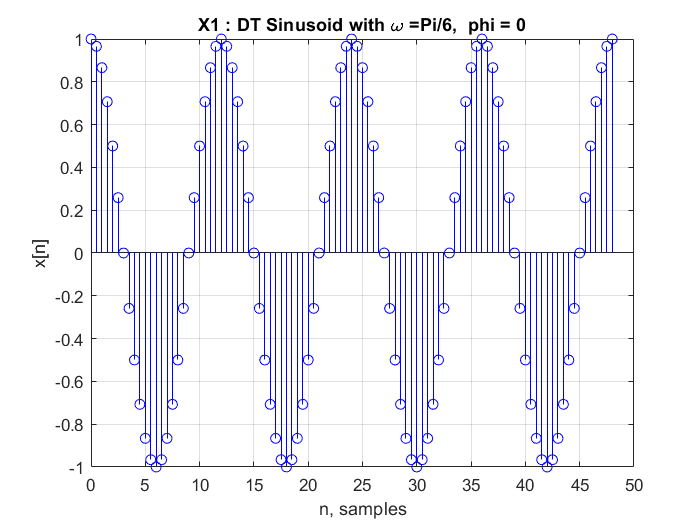

stem(n, sinusoidDT, 'b')
title('X1 : DT Sinusoid with \omega =Pi/6,  phi = 0')
xlabel('n, samples')
ylabel('x[n]')
grid

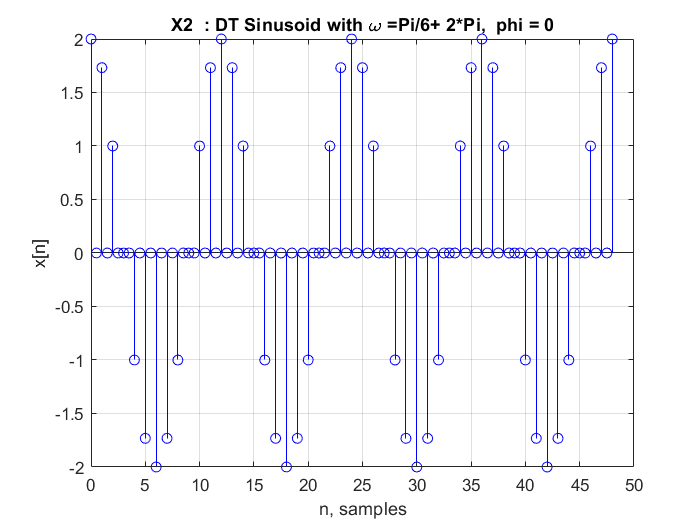

%Code to plot x2[n]

sinusoidDT2 = sinusoidDT+ cos((omega + pi*2)*n+0);  %Sinusoid with omega +2pi
stem(n, sinusoidDT2, 'b')
title('X2  : DT Sinusoid with \omega =Pi/6+ 2*Pi,  phi = 0')
xlabel('n, samples')
ylabel('x[n]')
grid

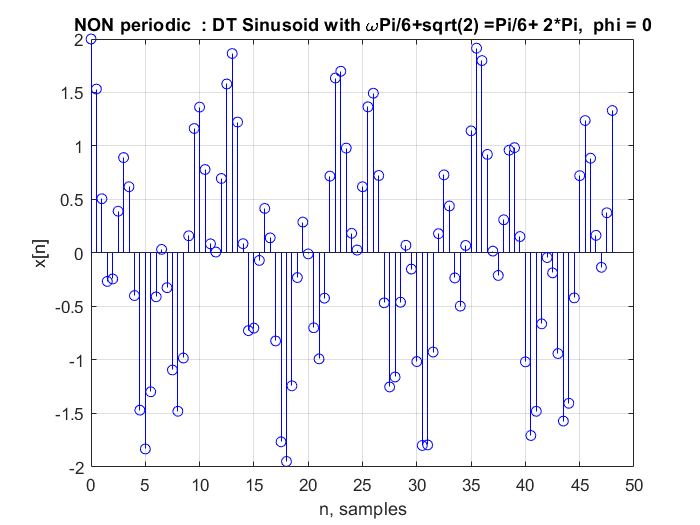

sinusoidDTNP = sinusoidDT+ cos((omega + sqrt(2))*n+0);  %omega is not integer multiple of 2pi so NON Periodic
stem(n, sinusoidDTNP, 'b')
title('NON periodic  : DT Sinusoid with \omegaPi/6+sqrt(2) =Pi/6+ 2*Pi,  phi = 0')
xlabel('n, samples')
ylabel('x[n]')
grid

%%%Uncomment to see plots visualizing omega from 0 to pi and pi to 2pi
% for omega=0:0.1:pi %To ensure we cross 2*pi exactly
%     sinusoidD = sinusoidDT+ cos((omega)*n+0);  %omega varies from 0 to pi 
%     stem(n, sinusoidD, 'b')
%     str="";
%     str=str+ " DT Sinusoid with omega= "+string(omega);
%     title(str)
%     xlabel('n, samples')
%     ylabel('x[n]')
%     drawnow         %To see all the plots of omega and visualize the changes
%     grid
% end
% for omega=pi:0.1:(pi*2) 
%     sinusoidD = sinusoidDT+ cos((omega)*n+0);  %omega varies from pi to 2pi 
%     stem(n, sinusoidD, 'b')
%     str="";
%     str=str+ " DT Sinusoid with omega= "+string(omega);
%     title(str)
%     xlabel('n, samples')
%     ylabel('x[n]')
%     drawnow         %To see all the plots of omega and visualize the changes
%     grid
% end

### **Inferences (10 Points):   **

 Now, play with the above constructed discrete-time sinusoid, make observations and write down your inference. 

- Is the $x\left\lbrack n\right\rbrack$ constructed by you periodic? 

              ANSWER:  Yes it looks periodic with period around 17-18 samples.

- Let $x_1 \left\lbrack n\right\rbrack =\;\cos \left(\omega_{0\;} n+\phi \right)$ (This is the sequence you have constructed above). Now, construct another sequence $x_2 \left\lbrack n\right\rbrack =\;\cos \left(\left(w_0 +2\pi \right)n+\phi \right)$ (You can write a separate snippet of code or modify appropriate variables in the above code itself). Based on your simulations, compare $x_1 \left\lbrack n\right\rbrack$ and $x_2 \left\lbrack n\right\rbrack$. Can you generalize your conclusion?

              ANSWER: The X2 is identical to X1 and looks to repeat in same time 

                                period but the figure x2 has less number of samples in any 

                                time interval than Figure X1. So X2 is not sampled properly.

- Now vary $\omega$, do you think that for every $\omega$, the sequence $x\left\lbrack n\right\rbrack$is periodic? If not, write down the condition on $\omega$ for $x\left\lbrack n\right\rbrack \;$to be periodic  

             ANSWER: No its not periodic for every $\omega$ , its periodic only when integer 

                                multiple of $\omega$ is another integer multiple of $2\pi$.

                                                                 
$$\textrm{ENTER}\;\textrm{YOUR}\;\textrm{EQUATION}\;\textrm{HERE}$$


- Now vary $\omega$ $0\;\textrm{to}\;2\pi$. What happens to the rate of oscillation of $x\left\lbrack n\right\rbrack$when $\omega$ is varied from $0\;\textrm{to}\;\pi$ and $\pi \;\textrm{to}\;2\pi$?  

              ANSWER:  Rate of oscillation first increases(o to pi) and then decreases

                                    from (pi to 2pi)

### CONCLUSIONS (10 Points)

- Compare and contrast the differences between continuous-time and discrete-time sinusoids. 

              ANSWER: 1)Continuous time signals are always periodic whereas 

                                    discrete time signals may not be periodic if integer multiple 

                                     of omega is not a integer multiple of 2pi.

                                2)As omega ($\Omega$) increases the the Period decreases but even 

                                    if the discrete time signal is periodic its period may not         

                                    necessarily decrease with increasing omega ($\omega$).

- Do the above conclusions hold true for continuous-time and discrete-time complex sinusoids, with $x\left(t\right)=\textrm{Aexp}\;j\left(\;\Omega t+\phi \right)\;\;$ and $x\left\lbrack n\right\rbrack =A*\exp \;j\left(\textrm{wn}+\phi \right)$, where $A$ is the amplitude.   

              ANSWER: Yes, any signal can be expressed using complex sinusoids. 

                                so results of continous time and discrete time will hold true 

                                even for complex sinusoids. 

# **Continuous-Time & Discrete-Time Sawtooth and Square Signals (40 Points)**

## Continuous-Time and Discrete-Time Square Signal

### **Coding (10 Points):                                                                   **

Question 1: Construct and plot a continuous-time square signal of a frequency and duty cycle of your choice. 

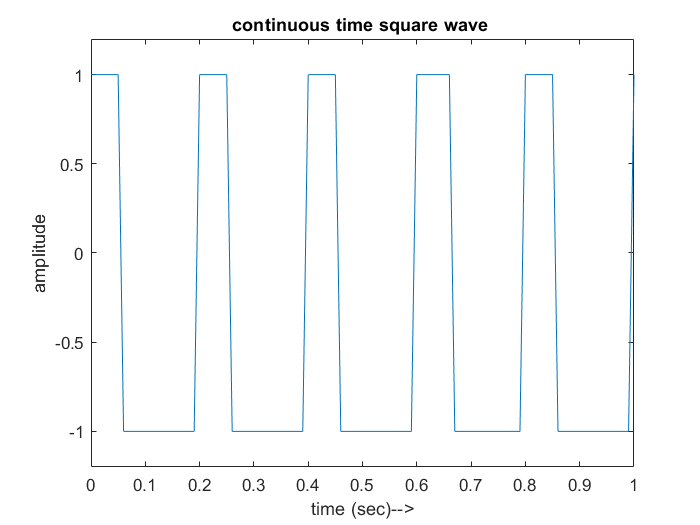

fs=100;  %we take sampling frequency 100Hz
duty=30;  %and duty cycle as 30%
F=5;      %we make a square wave of frequency 5 Hz
t=0:1/fs:1;
x1= square(2*pi*F*t,duty);
plot(t,x1);
axis([0 1 -1.2 1.2]);
ylabel('amplitude');
xlabel('time (sec)-->');
title('continuous time square wave ');



%t=0:0.1:20 %we make square wave of 20 seconds
%squarew=square(,)


Question 2: Now, sample the above signal with appropriate sampling frequency and plot the sequence.

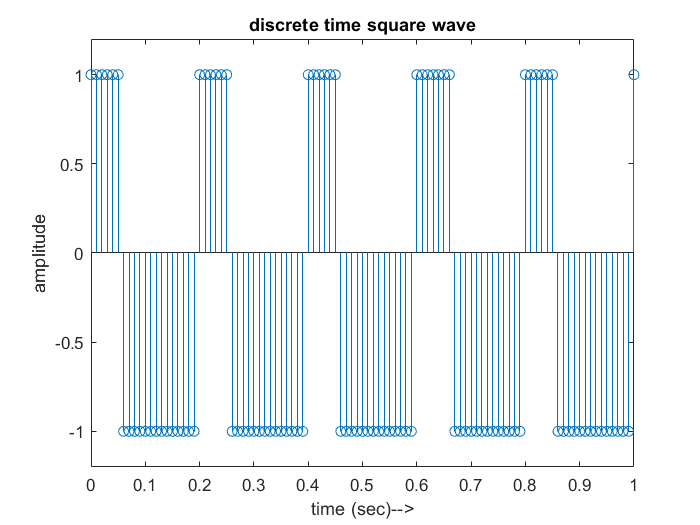

stem(t,x1);
axis([0 1 -1.2 1.2]);
ylabel('amplitude');
xlabel('time (sec)-->');
title('discrete time square wave');

display(x1);

x1 =      1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1


% WRITE YOUR CODE HERE

### Inference **(10 Points):     **

What are your observations?

  ANSWER: If sampling frequenct is not sufficiently higher ()than signal frequency out square wave gets 

                    distorted and takes shape between square and triangular. While if sampling frequency is 

                    greater than 20 times (100 Hz) the signal frequency (5 Hz)then there is no distortion in 

                    square wave. There is slight distortion even if sampling frequency if greater than 10 times 

                    (50 Hz)  the signal frequency of (5 Hz).

## Continuous-Time and Discrete-Time Triangular Signal

### **Coding (10 Points):                                                                   **

Question 1: Construct and plot a continuous-time triangular signal of parameters of your choice. 

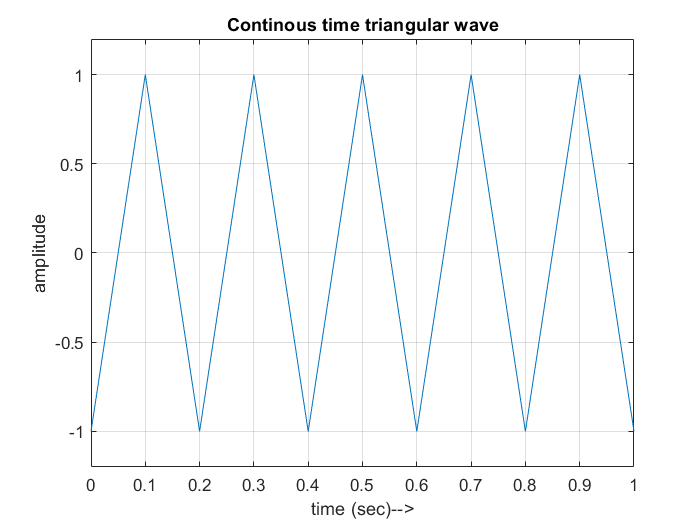

fs=100;     %The sampling frequency is 100 Hz
F=5;        %Frequency of wave
T= 1/F;     %Time period of the wave
t=0:1/fs:1; %so we get 5 periods
Tr = sawtooth(2*pi*F*t,1/2);
plot(t,Tr);
axis([0 1 -1.2 1.2]);
ylabel('amplitude');
xlabel('time (sec)-->');
title('Continous time triangular wave');
grid on

%plot(tr WRITE YOUR CODE HERE

Question 2: Now, sample the above signal with appropriate sampling frequency and plot the sequence.

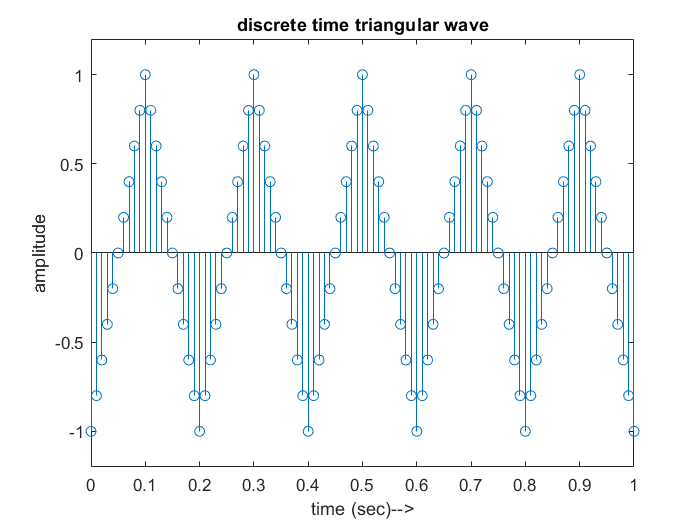

stem(t,Tr);
axis([0 1 -1.2 1.2]);
ylabel('amplitude');
xlabel('time (sec)-->');
title('discrete time triangular wave');

display(x1);% WRITE YOUR CODE HERE

x1 =      1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1


### Inference **(10 Points):     **

What are your observations?

  ANSWER: If sampling frequency is integer multiple of twice the signal frequency (10 Hz) we do not get 

                    distortion but otherwise we have distortion unless sampling frequency is greater than 

                    40 times($\left.\ge 200\mathrm{Hz}\right)$ the signal frequency (5 Hz). even with sampling frequency 101 Hz 

                    which is not an integer multiple of twice the signal frequency (10 Hz) we got some distortion 

                    but its very small at vertex . So for sampling frequency greater than 200 Hz (like 201 Hz) 

                    we can ignore the slight distortion in triangular wave.